% ADDT_SCRIPT   Generate dynamic library addt from addt.
% use mex -setup if compiler stops working

## Create configuration object of class 'coder.CodeConfig'.

mex=false;
if mex == true
    cfg = coder.config('mex');
else
    cfg = coder.config('lib','ecoder',false);
    cfg.GenerateReport = true;
    cfg.ReportPotentialDifferences = false;
    cfg.GenCodeOnly = true;
    cfg.Toolchain = 'MinGW64 | gmake (64-bit Windows)';
    cfg.BuildConfiguration = 'Debug';
    cfg.HardwareImplementation.ProdHWDeviceType = 'Intel->x86-64 (Mac OS X)';
    cfg.HardwareImplementation.TargetHWDeviceType = 'Intel->x86-64 (Mac OS X)';
end

## Define argument types for entry-point 'addt'.

ARGS = cell(1,1);
ARGS{1} = cell(19,1);   % 3 required input arguments + 8 name / pairs
% required input arguments
% y: a column vector of doubles of any length
% R.L. just to have a confirmation about thhe first value of coder.typeof
% If it is a double any array of doubles will work?
% [Inf 1] = a column vector of doubles of any length
% [1, 0] = dynamic number of rows but just one column
ARGS{1}{1} = coder.typeof(0,[Inf 1],[1 0]);
% X: an array of doubles of any dimensions
ARGS{1}{2} = coder.typeof(0,[Inf Inf],[1 1]);
% w: a column vector of doubles of any length
ARGS{1}{3} = coder.typeof(0,[Inf 1],[1 0]);
% optional input arguments (name / pairs)
ARGS{1}{4} = coder.Constant('intercept');
% a scalar boolean
ARGS{1}{5} = coder.typeof(true);
ARGS{1}{6} = coder.Constant('la');
% a scalar or an empty value
% R.L. coder.typeof(0) is equivalent to coder.typeof(0, [1 1], [0 0]) ?
ARGS{1}{7} = coder.typeof(1,[1 1],[1 1]);
ARGS{1}{8} = coder.Constant('nocheck');
% a scalar or an empty value
ARGS{1}{9} = coder.typeof(0);

% R.L. the following name / pairs are not needed to the
% coder section of addt.m that will be compiled.
% It is necessary to provide them as well or can we skip
% the declaration? The second option would be much better.
ARGS{1}{10} = coder.Constant('plots');
% a scalar or an empty value
ARGS{1}{11} = coder.typeof(0);
ARGS{1}{12} = coder.Constant('FontSize');
% a scalar or an empty value
ARGS{1}{13} = coder.typeof(0);
ARGS{1}{14} = coder.Constant('SizeAxesNum');
% a scalar or an empty value
ARGS{1}{15} = coder.typeof(0);
ARGS{1}{16} = coder.Constant('textlab');
% a boolean
ARGS{1}{17} = coder.typeof(true);
ARGS{1}{18} = coder.Constant('units');
% a column array of any length
ARGS{1}{19} = coder.typeof(0,[Inf 1],[1 0]);

## Invoke MATLAB Coder.

codegen -config cfg addt -args ARGS{1}

Code generation successful: View report




%
cd ./codegen/lib/addt;
load buildInfo.mat
packNGo(buildInfo,'packType', 'hierarchical', 'minimalHeaders',true, 'fileName','addt');



When we run the MATLAB Coder App and we try to convert addt.m the following warning occurs, even if we already made the following modifications to the code of addt.m:

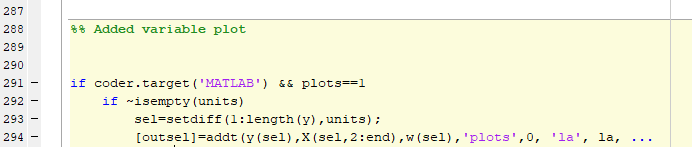

In other words the instruction coder.target('MATLAB') is not taken into account.

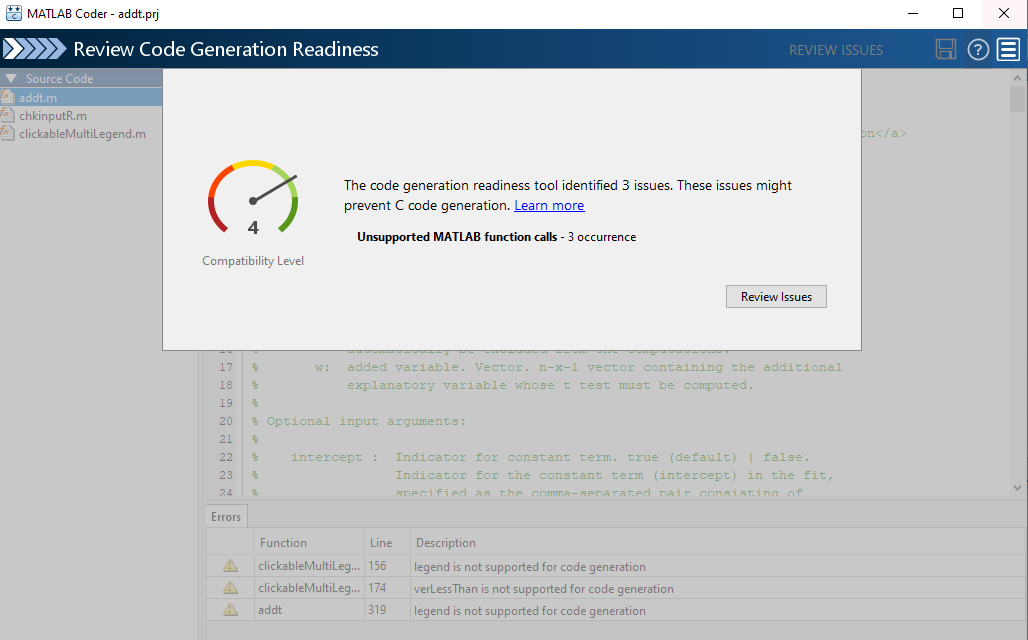

How is it possible to load the addt_script.m file into the MATLAB Coder App? Being able to import the manual definitions of the input parameters into the App could be a convenient additional possibility.